AUC=[] % generates data table to store each trials AUC vals


AUC =

     []



time=-10:0.5:20 %%INPUT  pretime:increment:posttime
name='UniqueFileName_AUC'%%INPUT 'UniqueFileName'

name = 'E2S_AUC'

x=E2S %%INPUT x=datatable to be analyzed with each trial in a separate rows. Change "datatable" to desired table for analysis
% OPTIONAL INPUT for binned AUC Values (default in code is 2s bins)
% Time increments for AUC values to be calculated. Should be spaced with
%even increments to avoid errors on final bar plot
%in this example values should be replaced where the R's are
%AUC(:,1)=trapz(x(:,time(1,:) >R & time(1,:) < R),2);
AUC(:,1)=trapz(x(:,time(1,:) >-2 & time(1,:) < 0),2);
AUC(:,2)=trapz(x(:,time(1,:) >0 & time(1,:) < 2),2);
AUC(:,3)=trapz(x(:,time(1,:) >2 & time(1,:) < 4),2);
AUC(:,4)=trapz(x(:,time(1,:) >4 & time(1,:) < 6),2);
AUC(:,5)=trapz(x(:,time(1,:) >6 & time(1,:) < 8),2);
AUC(:,6)=trapz(x(:,time(1,:) >8 & time(1,:) <10),2);
AUC(:,7)=trapz(x(:,time(1,:) >10 & time(1,:) <12),2);
AUC(:,8)=max(x,[],2)
% Find mean and error of all AUC values
AUCmean=mean(AUC);
AUCsem=std(AUC)/sqrt(height(AUC));
% INPUT n= increment spacing for AUC values to add labels on graph 
% i.e. first value of first bin:increment:first value of last bin
% if spacing is not equal - manually generate table of time values
% default below is -2 to 12 s in 2-sec bins
n=[-2:2:12]
%%plot and summary data. do not edit
AUCgraph=bar(n,AUCmean(:,1:8))

AUCgraph =   Bar with properties:

    BarLayout: 'grouped'
     BarWidth: 0.8000
    FaceColor: [0 0.4470 0.7410]
    EdgeColor: [0 0 0]
    BaseValue: 0
        XData: [-5 0 5 10 15 20 25 30]
        YData: [-0.4248 1.9573 1.2514 0.7552 -0.1776 -0.2841 -0.2921 2.9075]

  Show all properties


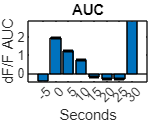

hold on
er=errorbar(n(:,1:7),AUCmean(:,1:7),AUCsem(:,1:7),AUCsem(:,1:7));
er.Color=[0 0 0];
er.LineStyle = 'none';
title('AUC')
xlabel('Seconds')
ylabel('dF/F AUC')
hold off
saveas(AUCgraph,name,'png')

writematrix(AUC,name,'FileType','Spreadsheet')

CumAUC=cumtrapz(AUC(:,3:7),2);
name2=[name,"AUC_Cumm"];
Cname= join(name2);
writematrix(CumAUC,Cname,'FileType','Spreadsheet')
